# Taller de Matlab #1 - Series de Taylor

Andrés Fernando Aranguren Silva - afarangurens@unal.edu.co

## 1. Marco Teórico.

1.1 Serie de Taylor

En matemáticas, una serie de Taylor es una aproximación de funciones mediante una serie de potencias  o suma de potencias enteras de términos como $(x-a)^n$ llamado también el n-ésimo polinomio de Taylor, dicha suma se calcula a partir de las derivadas de la función para un determinado valor $a$ suficientemente derivable sobre la función. 

1.2 Definición formal de una Serie de Taylor:

La serie de Taylor se define matemáticamente como una serie de potencias:

$f(a) + \frac{f' (a)}{1!}(x-a) + \frac{f'' (a)}{2!}(x-a)^2 + \frac{f''' (a)}{3!}(x-a)^3 + ...,$  donde:

- $n!$es el factorial de n.

- $f^n (a)$ denota la n-ésima derivada de $f$para el valor $a$ de la variable respecto de la cual se deriva.

Se puede reescribir de una forma más compacta con la notación sigma de la siguiente manera:

- 
$$f(x) = \sum_{n=0}^{\infty}{\frac{f^n (a)}{n!}}(x-a)^n$$


1.3 Serie de Taylor para determinar $ln(x)$

Se desea calcular el valor de $ln(x)$ a través de una aproximación de función con series de Taylor. Para poder realizar esto se debe conocer un punto $x_0$ en el cual se pueda calcular facilmente $ln$ y todas sus derivadas. El punto más intuitivo a utilizar es 1, pues el $ln$ de este punto es fácilmente calculable ya que$ln(1) = 0$, por tanto escogemos $x_0 = 1$.


$$f(x) = ln(x)$$



$$f(x) = ln(x) = \frac{f^0(x_0)}{0!} + \frac{f' (x_0)}{1!}(x - x_0)^1 + \frac{f'' (x_0)}{2!}(x-x_0)^2 + ..

= \sum_{n=0}^{\infty}{\frac{f^n (a)}{n!}}(x-a)^n$$


Cálculo de las primeras 4 derivadas para encontrar un patrón y poder intuir la fórmula:

- 
$$f^0(x) = f(x) = ln(x)$$
                      
$$\rightarrow$$

$$f^0(x_0) = ln(x_0) = ln(1) = 0$$


- 
$$f'(x) = x^{-1}$$
                                    
$$\rightarrow$$

$$f'(x_0) = x_0^{-1} = 1^{-1} = 1= 0!$$


- 
$$f''(x) = (-1)x^{-2}$$
                            
$$\rightarrow$$

$$f''(x_0) = (-1)x_0^{-2} = (-1)1^{-2} = -1!$$


- 
$$f'''(x) = (-2)(1)x^{-3}$$
                       
$$\rightarrow$$

$$f'''(x_0) = (-2)(1)x_0^{-3} = (-2)(1)1^{-3} = 2!$$


- ...

- 
$$f^n(x) = [-(n-1)]...(-2)(-1)x^{-n}$$
   
$$\rightarrow$$

$$f^n(x_0) =  [-(n-1)]...(-2)(-1)x_0^{-n} = (-1)^{n-1} (n-1)!$$


Entonces:

$f(x) = ln(x) =  \sum_{n=0}^{\infty}{\frac{f^n (x_0)}{n!}}(x-x_0)^n$  y debido a que $f^0(x_0) = 0$ el $n$ empieza desde 1, por tanto:

                    $=  \sum_{n=1}^{\infty}{\frac{f^n (x_0)}{n!}}(x-x_0)^n$, como $x_0 = 1$, la expresión queda:


$$f(x) = ln(x) =  \sum_{n=1}^{\infty}\frac{{(-1)^{n-1}}}{n}(x-1)^n$$


## 2. Obtención de Polinomios de Taylor.

Ahora se deben obtener los polinomios de Taylor de grado 2, 5, 8 y 15:

clc 
clear
close all
x_0 = 1

x_0 =      1


syms x

p2 = Pol(x_0, 2)

$$p2 = x-\frac{{\left(x-1\right)}^{2}}{2}-1$$

p5 = Pol(x_0, 5)

$$p5 = x-\frac{{\left(x-1\right)}^{2}}{2}+\frac{{\left(x-1\right)}^{3}}{3}-\frac{{\left(x-1\right)}^{4}}{4}+\frac{{\left(x-1\right)}^{5}}{5}-1$$

p8 = Pol(x_0, 8)

$$p8 = x-\frac{{\left(x-1\right)}^{2}}{2}+\frac{{\left(x-1\right)}^{3}}{3}-\frac{{\left(x-1\right)}^{4}}{4}+\frac{{\left(x-1\right)}^{5}}{5}-\frac{{\left(x-1\right)}^{6}}{6}+\frac{{\left(x-1\right)}^{7}}{7}-\frac{{\left(x-1\right)}^{8}}{8}-1$$

p15 = Pol(x_0, 15)

$$p15 = x-\frac{{\left(x-1\right)}^{2}}{2}+\frac{{\left(x-1\right)}^{3}}{3}-\frac{{\left(x-1\right)}^{4}}{4}+\frac{{\left(x-1\right)}^{5}}{5}-\frac{{\left(x-1\right)}^{6}}{6}+\frac{{\left(x-1\right)}^{7}}{7}-\frac{{\left(x-1\right)}^{8}}{8}+\frac{{\left(x-1\right)}^{9}}{9}-\frac{{\left(x-1\right)}^{10}}{10}+\frac{{\left(x-1\right)}^{11}}{11}-\frac{{\left(x-1\right)}^{12}}{12}+\frac{{\left(x-1\right)}^{13}}{13}-\frac{{\left(x-1\right)}^{14}}{14}+\frac{{\left(x-1\right)}^{15}}{15}-1$$

Para esto se crean 3 funciones una para manejar cada uno de los términos de la expresión, uno para calcular la n-ésima derivada, otro para calcular el factorial, y la última para calcular e imprimir los n primero polinomios de la expresión, estos se encuentran al final del archivo.

## 3. Gráficas.

A continuación se grafica los polígonos obtenidos en el punto anterior, para así poder contrastar como los polígonos se van acercando cada vez más a la función $ln(x)$ a medida que aumenta el grado del polígono.

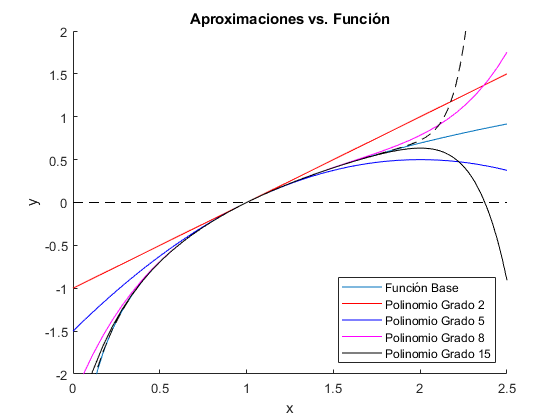

figure(1)
hold on
title('Aproximaciones vs. Función')
xlabel('x')
ylabel('y')
xlim([0 2.5])
ylim([-2 2])
fplot(log(x))
fplot(Pol(x_0,1), 'r')
fplot(Pol(x_0, 2), 'b')
fplot(Pol(x_0, 5), 'm')
fplot(Pol(x_0, 8), 'k')
fplot(Pol(x_0, 15), 'k--')
fplot(0, 'k--')
legend('Función Base', 'Polinomio Grado 2', 'Polinomio Grado 5', 'Polinomio Grado 8', 'Polinomio Grado 15','Location','southeast')
hold off

## **4. Determinación del Valor de Aproximación.**

Ahora se debe calcular el valor de la función $ln(x)$ para $x=2$, para cada uno de los polígonos obtenidos en el punto **3. **Adicional a esto se compara el nivel de aproximación mediante errores absolutos y se despliegan en forma de tabla.

M = zeros(4,3);
x = 2;
yRef = log(x);
disp(['Valor de Referencia: ' num2str(yRef)]);

Valor de Referencia: 0.69315


M(:,1) = [2, 5, 8, 15];
M(:,2) = [eval(p2), eval(p5),eval(p8),eval(p15)];
M(:,3) = [ERAbs(M(1,2),log(x)),ERAbs(M(2,2),log(x)),ERAbs(M(3,2),log(x)),ERAbs(M(4,2),log(x))];
T = array2table(M,"VariableNames",["Grado del Polinomio",'Valor Evaluado','Error Absoluto'])

T = 4×3 table
    Grado del Polinomio     Valor Evaluado        Error Absoluto  
    ___________________    _________________    __________________

             2                           0.5     0.193147180559945
             5             0.783333333333333    0.0901861527733879
             8             0.634523809523809     0.058623371036136
            15              0.72537185037185    0.0322246698119047


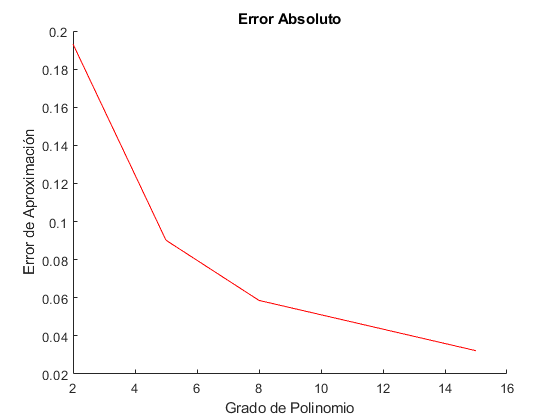


figure(2)
hold on 
title('Error Absoluto')
xlabel('Grado de Polinomio')
ylabel('Error de Aproximación')
plot(M(:,1), M(:,3), 'r')
hold off

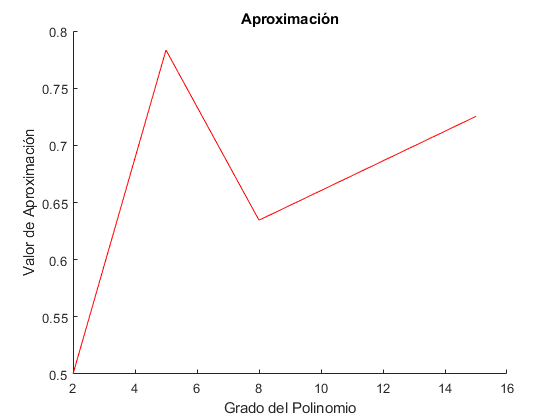


figure(3)
hold on
title('Aproximación')
xlabel('Grado del Polinomio')
ylabel('Valor de Aproximación')
plot(M(:,1), M(:,2), 'r')
hold off

## 5. Análisis Gamma y Resto de Taylor.

Se utiliza el teorema del resto de Taylor para determinar el valor máximo de error de la aproximación, en este caso para el polinomio de grado 15 ( $n=15$ ). Este se calcula de la siguiente forma:

$R_n (x)=  \frac{{f^{n+1}(z)}}{(n+1)!}(x-c)^{n+1}$, donde para el caso de este ejercicio $c = x_0 = 1$, $x = 2$ y $z$  es un número donde la derivada $f^{n+1}(z)$ sea máxima para $n=15%$, entre $c$.y $x$

format long
fRes = RES(1,2,15)

$$fRes = -\frac{1}{16\,y^{16}}$$

yRefPol = M(4,2)

yRefPol =    0.725371850371850


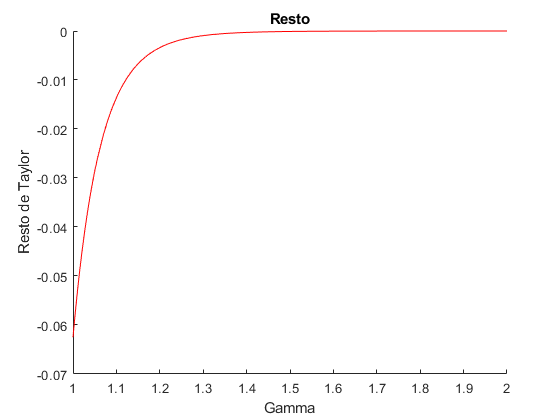


figure(4)
hold on
title('Resto')
xlabel('Gamma')
ylabel('Resto de Taylor')
xlim([1 2])
fplot(fRes, 'r')
hold off


m = 150;
t = abs(1 - 2) / (m);

for i = 1:m
    y = 1 + (i*t);
    Y(i, 1) = eval(fRes);
end
Residuo = max(abs(Y)) % Valor del error máximo

Residuo =    0.056196466049649


Una vez calculado el residuo del resto, se calculan los intervalos de acotación para $ln(2)$, los cuáles se encuentran sumando y restando el residuo al valor de referencia, el cual en este caso es la aproximación al valor de $ln(2)$ con un polinomio de grado 15.

% Intervalo superior
yUP = yRefPol + abs(Residuo)

yUP =    0.781568316421499



yRef

yRef =    0.693147180559945



% Intervalo inferior
yDWN = yRefPol- abs(Residuo)

yDWN =    0.669175384322201


## 5. Grado Óptimo del Polinomio según Tolerancia.

A partir de una tolerancia $1x10^{-6}$ se determina a continuación el grado del polinomio óptimo para aproximar el valor $ln(2)$, para esto usamos la fórmula del error: $E_n (x)=  \frac{{f^{n+1}(z)}}{(n+1)!}(x-c)^{n+1}$

tolerancia = 0.000001;
res = 1;
n = 1;
A = zeros(2);
while res >= tolerancia
    res = abs((dfN(n,x_0) * (x-x_0)^(n+1))/FRL(n+1));
    A(n,1) = n;
    A(n,2) = res;

    n = n + 1;
end

K = array2table(A,"VariableNames",["Grado", "Residuo"])

K = 170×2 table
    Grado          Residuo      
    _____    ___________________

      1                      0.5
      2        0.166666666666667
      3       0.0833333333333333
      4                     0.05
      5       0.0333333333333333
      6       0.0238095238095238
      7       0.0178571428571429
      8       0.0138888888888889
      9       0.0111111111111111
     10      0.00909090909090909
     11      0.00757575757575758
     12      0.00641025641025641
     13      0.00549450549450549
     14      0.00476190476190476
     15      0.00416666666666667
     16      0.00367647058823529


El resultado da, que para el polinomio de grado 170, el error se hace igual a la tolerancia dada en el ejercicio.

## 6. Funciones utilizadas.

function fact = FRL(n)
    k = n;
    fact = 1;
    for i = 1:k
        fact = fact * i;
    end
end

function der = dfN(n,x0)
    der = (-1)^(n-1) * FRL(n-1) * (x0)^(-1*n);
end

function pol = Pol(x0,n)
    syms x
    pol = 0;
    for i = 1:n  
        pol = pol + (dfN(i,x0)*((x-x0)^i)/FRL(i));
    end
end

function eAbs = ERAbs(POL,F)
    eAbs = abs(POL-F);
end

function rest = RES(x0, x, n)
    syms y
    k = n+1;
    rest = dfN(k,y)*((x-x0)^k) / FRL(k);
end

## 7. Referencias

[1] [https://www.youtube.com/watch?v=lY0LzJXTgeo&ab_channel=TheOrganicChemistryTutor](https://www.youtube.com/watch?v=lY0LzJXTgeo&ab_channel=TheOrganicChemistryTutor)

[2] T. Flórez. Métodos Numéricos para Estudiantes de Ingeniería. Publicaciones Facultad de Ingeniería.

[3] [https://la.mathworks.com/help/matlab/index.html?s_tid=CRUX_topnav](https://la.mathworks.com/help/matlab/index.html?s_tid=CRUX_topnav)

[4] Montoria_Series.pdf, Juan Manuel Rubio Vanegas.